%% AUTHOR INFORMATION
% NAME: Ashwin Balagopal S
% EMAIL: ee17d200@smail.iitm.ac.in
% Code to analyse the output from ./Test_Write_Drivers

## Preface

    clear ;
    clc ;
    if( ~exist( 'globalVars', 'var' ) )
        globalVars=[];
    end
    eval( [ 'clearvars -except globalVars ' sprintf( '%s ', globalVars ) ] ) ;
    close all ;
    zeroes = @( x ) zeros( x ) ;

## Go to Global

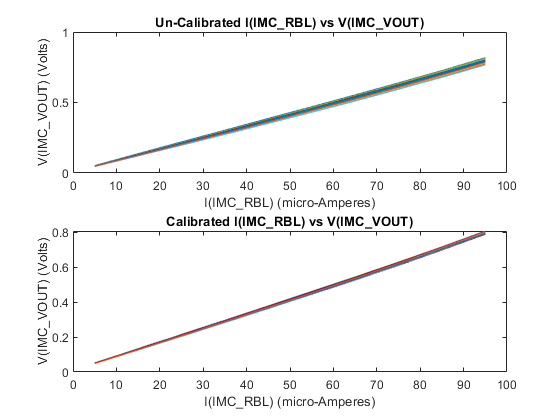

% Global : D:\Xilinx\Vivado_2018_Projs\Srinidhi_Laptop\PCB_TEST_FPGA_ARM\Character_Files\new_C_code_UART_files\10_vecfile_auto_FA\7_vecfile_auto_FA
% cd( '../../../' ) ;
%     fileName = mfilename ; 
    filePath = matlab.desktop.editor.getActiveFilename ;
    b = find( filePath == '\', 1, 'last' ) ; 
    fileName = filePath( ( b + 1 )  : ( end - 4 ) ) ;
    b = find( fileName == '_', 1, 'last' ) ; 
    sourceFileName = fileName( 1 : ( b - 1 ) ) ;
driverCode_fileName         = sprintf( '/%s', sourceFileName ) ;
filePath            = '.' ;
fpgaReceivedFile_name       = [ filePath '/fpgaRcvdFiles' driverCode_fileName ] ;
[    fpgaReceivedFile_decrypted ...
            , adc_VPVN ...
            , adc_AUX00 ...
            ,    SA_SC_collect    ...
            ,    ADC_SC_collect  ...
            ,    AdderTree_SC_collect  ...
            ,    SARTIMING_OUT_SC_collect  ...
            ,    WRITE_2_SC_collect  ...
            ,    WRITE_1_SC_collect  ...
            ,    WRITE_0_SC_collect  ...
            ,    IMC_RBL_SC_collect  ...
            ,    IMC_VOut_SC_collect  ...
            ,    WWL_SC_collect  ...
            ,    FLOATADC_SC_collect  ...
            ,    SARTIMING_IN_SC_collect  ...
            ,    ControlPath_SC_collect  ...
            ,    Reset_DFF_collect  ...
            ,    SAR_Bin_Num ...
           ,     read_SRAM_collect_Cell ] = decrypt_and_RSC( fpgaReceivedFile_name ) ;
%% cd'ing back
    cd( filePath ) ;
%% saving data
    c = clock ;
    year    = c(1) ;
    month   = c(2) ; 
    day     = c(3) ;
    hour    = c(4) ;
    minute  = c(5) ;
    seconds = floor(c(6)) ;
save( [ sprintf( './analyzeResults/%s_%s_%d_%d_%d', fileName, date,hour,minute,seconds) ] ) ;
currentValuesAbs_array=[5E-06:10E-06:95E-06];
MAC_Xfers_calib=reshape(adc_VPVN,10,[]);
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v3\MATLAB_CONTROL\Control_Codes\Testing\011_CurrentMirrorFunctionality\MAC_xfers_unCalib.mat');
MAC_xfers_unCalib=MAC_xfers;
subplot(2,1,1)
plot(currentValuesAbs_array*1E6,MAC_xfers_unCalib);
title('Un-Calibrated I(IMC\_RBL) vs V(IMC\_VOUT)');
xlabel('I(IMC\_RBL) (micro-Amperes)');
ylabel('V(IMC\_VOUT) (Volts)');

subplot(2,1,2)
plot(currentValuesAbs_array*1E6,MAC_Xfers_calib);
title('Calibrated I(IMC\_RBL) vs V(IMC\_VOUT)');
xlabel('I(IMC\_RBL) (micro-Amperes)');
ylabel('V(IMC\_VOUT) (Volts)');



m1R=(MAC_Xfers_calib(end,:)-MAC_Xfers_calib(2,:))/(currentValuesAbs_array(end)-currentValuesAbs_array(2));
save('m1R_1X.mat','m1R');

